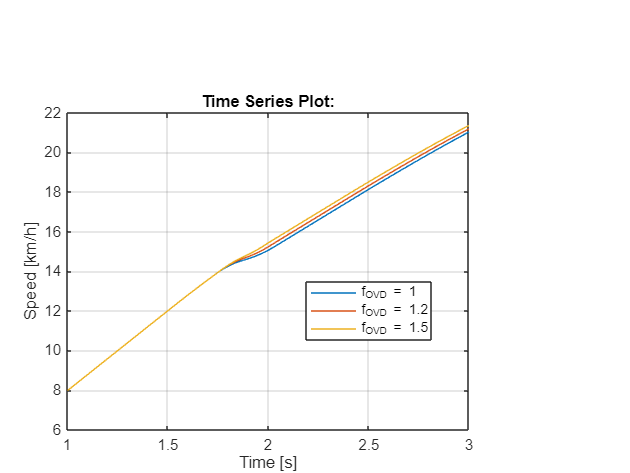

files = ["TDT1.mat", "TDT1.2.mat", "TDT1.5.mat"];

f_OVD = [1, 1.2, 1.5];

figure()

for i = 1:length(files)

    load(files(i));

    plot(out.v_TDT1, "DisplayName", "f_{OVD} = " + string(f_OVD(i)));
    hold on;

end
grid on
xlim([1 3])
xlabel("Time [s]");
ylabel("Speed [km/h]");
legend("Location", "best");

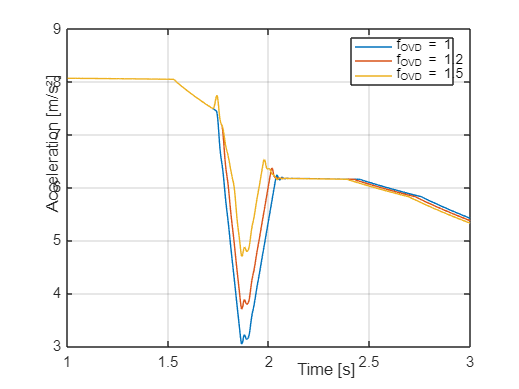


figure()
for i = 1:length(files)

    load(files(i));

    plot(out.acc_TDT1, "DisplayName", "f_{OVD} = " + string(f_OVD(i)));
    hold on;

end
grid on
xlim([1 3])
xlabel("Time [s]");
ylabel("Acceleration [m/s²]");
legend("Location", "best");

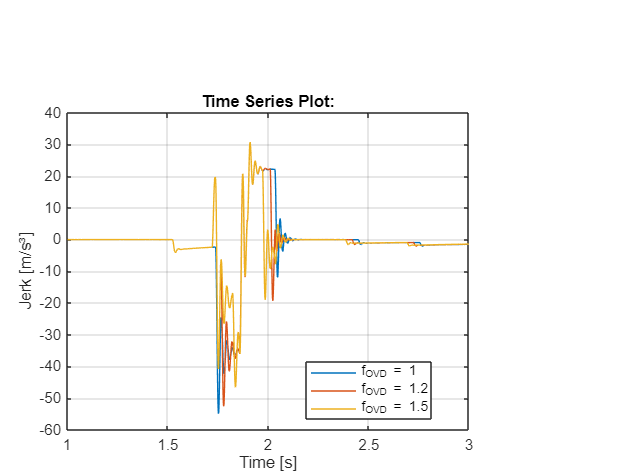


figure()
for i = 1:length(files)

    load(files(i));

    plot(out.jerk_TDT1, "DisplayName", "f_{OVD} = " + string(f_OVD(i)));
    hold on;

end
grid on
xlim([1 3])
xlabel("Time [s]");
ylabel("Jerk [m/s³]");
legend("Location", "best");